# Introduction to MATLAB

### and how it can make your homework easier

## Crash course about live scripts

This is a live script. It works differently from m-files (which is the traditional way of writing MATLAB code). Live scripts are great for exploratory analysis and for describing the code with text (like this). They work similar to `nb-`files (`Mathematica`) and `ipynb`-files (`Python`, `R`, `Julia` etc.)

Code is divided up into cells:

a = 1+1

a =      2


As you can see, all output will be displayed to the right $\to$

By setting section breaks (Ctrl+Alt+Enter), these cells can be run (Ctrl+Enter) separately and in any order that you want.

b = a*2

b =      4


They can also have interactive widgets inside the code. Changing widgets will rerun the cell.

x = -70;
y = x*b

y =   -280


Plots will also appear in the window to the right $\to$

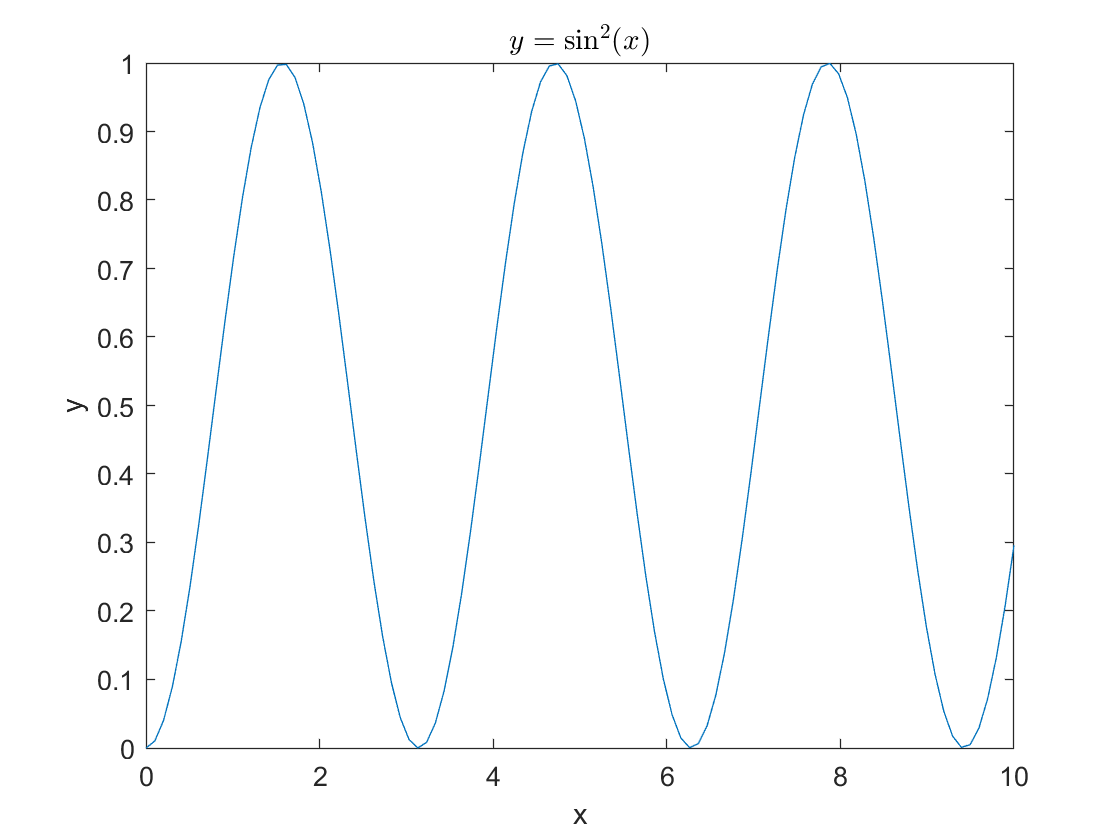

x = linspace(0, 10, 100);
y = sin(x).^2;
plot(x, y)
xlabel('x'), ylabel('y')
title('$y=\sin^2(x)$', 'Interpreter',"latex")

The live editor even supports `LaTeX!`


$$\int_0^{2\pi} \sin^2(x)dx = \pi$$


integral(@(x)sin(x).^2, 0, 2*pi)

ans =    3.141592653589793


## Solving homework

We will try and solve some questions in one of my text books on differential equations:

### Example 1

For 


$$A = \left[{\matrix{8&1&6\cr 3&5&7\cr 4&9&2}}\right] , ~\vec{b} = \left[{\matrix{1\cr 2\cr 3}}\right]$$


A = magic(3);
b = (1:3)';

**1: **Find the eigenvectors and eigenvalues of $A$

[eigen_vectors, eigen_values] = eig(A)

eigen_vectors =   -0.577350269189626  -0.813052529585141  -0.341648008794110
  -0.577350269189626   0.471404520791032  -0.471404520791032
  -0.577350269189626   0.341648008794110   0.813052529585142


eigen_values =   15.000000000000004                   0                   0
                   0   4.898979485566361                   0
                   0                   0  -4.898979485566358


Just 1 line of code!

**2:** Solve for $\vec{x}$ in


$$A\vec{x} = \vec{b}$$


x = A\b

x =    0.050000000000000
   0.300000000000000
   0.050000000000000


Once again, 1 line of code!

### Example 2

Given the differential equation


$$\frac{dy}{dt} = 2ty^2$$


**1:** Solve the differential equation

syms y(t)
differential_equation = diff(y, t) == 2*t*y^2

$$differential\_equation(t) = \frac{\partial }{\partial t}y\left(t\right)=2\,t\,{y\left(t\right)}^{2}$$

all_solutions = dsolve(differential_equation)

$$all\_solutions = \left(\begin{array}{c} -\frac{1}{t^{2}+C_{1}}\\ 0 \end{array}\right)$$

solution = all_solutions(1)

$$solution = -\frac{1}{t^{2}+C_{1}}$$

With just 3 (4) lines, we managed to solve the first problem!

**2:** Plot several solutions of the given differential equation. Describe how solutions appear to behave as $t$ increases and how their behavior depends on the initial value $y_0$ when $t=0$.

y_0 = -6;
all_solutions = dsolve(differential_equation, y(0) == y_0);
solution = all_solutions(1)

$$solution = -\frac{1}{t^{2}+\frac{1}{6}}$$

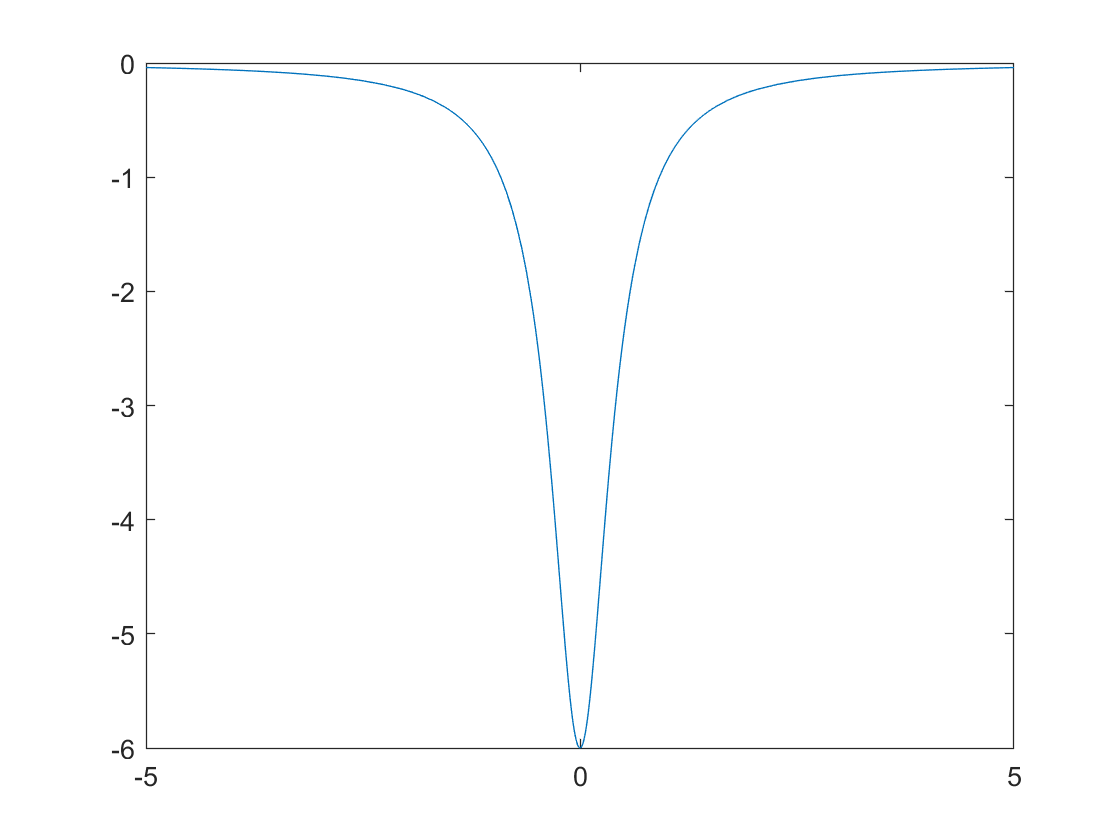

fplot(solution)

%yline(0, 'r')

We can check multiple solutions of the differential equation just by using the slider. Even the asymptotes are automatically plotted!

## Conclusion

As we have seen, MATLAB is a great tool for linear algebra, but also for solving differential equations, symbolic math, and visualization. Furthermore, being able to try differnt parameters in the live script makes it easy to explore different scenarios.

### Easter egg

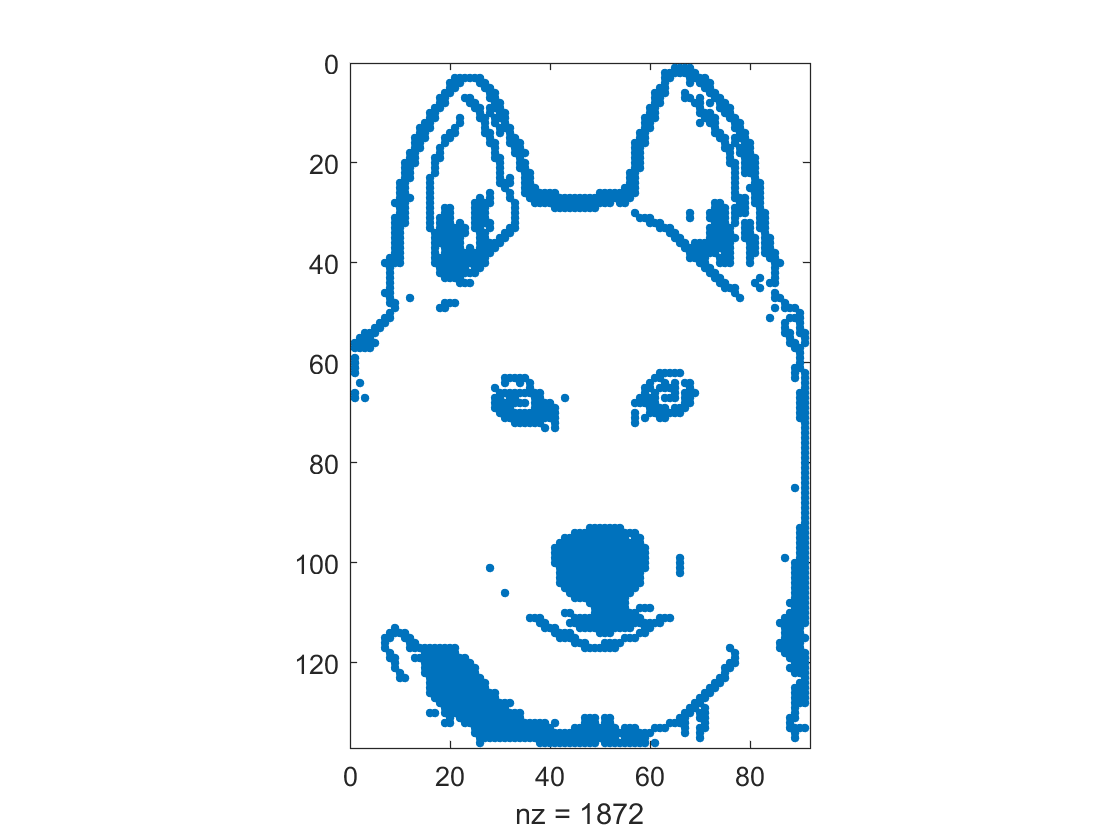

spy